# **Simulación 6 Robots**

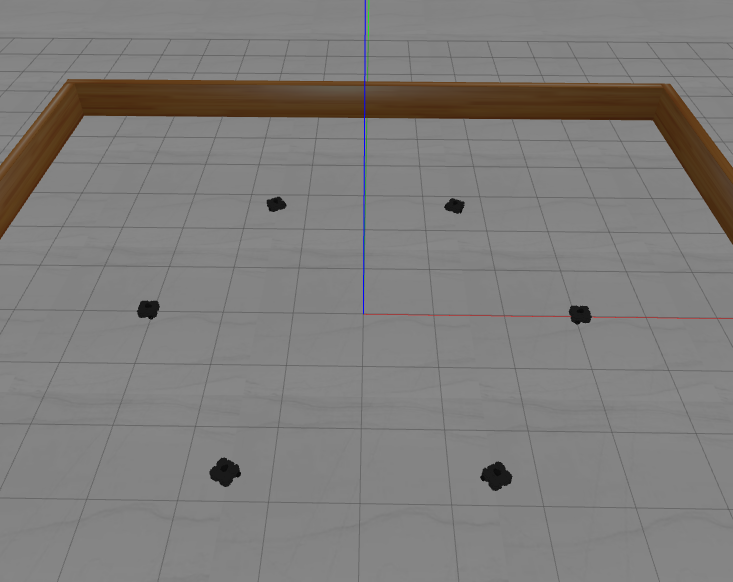

## Simulación

- Mapa con 6 agentes

% setup enviroment 
clear, clc, close all

Tiempo de Simulación:

% Variables de inicialización
t_sim=30;

Ajuste controlador VFH+ y Pure Pursuit:

%%Inicialización controlador PurePursuit
PP=controllerPurePursuit;
% PP.Waypoints=Way;
PP.MaxAngularVelocity=1.82; %rad/s 
PP.DesiredLinearVelocity=0.2;% m/s
PP.LookaheadDistance=0.5; %m 
%%Inicialización Algoritmo VFH
VFH = controllerVFH;
VFH.UseLidarScan=true;
VFH.NumAngularSectors=360;
VFH.DistanceLimits=[0.3, 3.5];
VFH.RobotRadius=0.22;
VFH.SafetyDistance=0.35;
VFH.MinTurningRadius=0.4;
VFH.HistogramThresholds=[5,25];


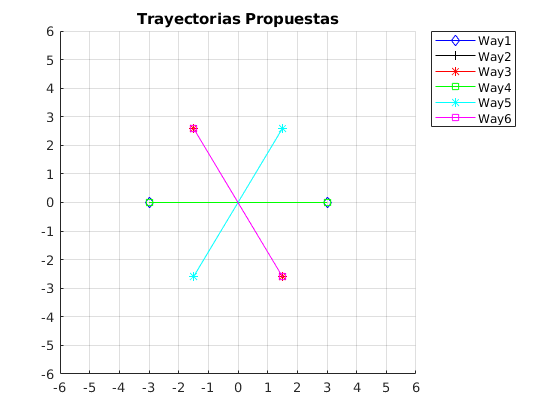

P=zeros(6,2);
l=3;
for i=1:6
    P(i,1)=l*cosd((i-1)*60);
    P(i,2)=l*sind((i-1)*60);
end

Way1=[P(1,:);P(4,:)];
Way2=[P(2,:);P(5,:)];
Way3=[P(3,:);P(6,:)];
Way4=[P(4,:);P(1,:)];
Way5=[P(5,:);P(2,:)];
Way6=[P(6,:);P(3,:)];

 
figure()
hold on

plot(Way1(:,1),Way1(:,2),'b-d');
plot(Way2(:,1),Way2(:,2),'k-+');
plot(Way3(:,1),Way3(:,2),'r-*');
plot(Way4(:,1),Way4(:,2),'g-s');
plot(Way5(:,1),Way5(:,2),'c-*');
plot(Way6(:,1),Way6(:,2),'m-s');

xticks(-6:6)
yticks(-6:6)
grid on
xlim([-6,6])
ylim([-6,6])
title("Trayectorias Propuestas")
hold off
legend("Way1","Way2","Way3","Way4","Way5","Way6","Location","bestoutside")

# Ejecutar 

# Six_Robots.slx

## Information log from simulation

Ejecutar al finalizar la ejecución del .slx

%Data robot 1
t1=actuators1.time;
U1=actuators1.signals.values(:,1);
W1=actuators1.signals.values(:,2);
Lidar1.angles=angles1.signals.values;
Lidar1.ranges=ranges1.signals.values;
X1=pose1.signals.values(:,1);
Y1=pose1.signals.values(:,2);
YAW1=pose1.signals.values(:,3);
TD1=targetDir1.signals.values(1,:);
[it_max1,~]=size(Lidar1.ranges);
CG_1=CG1.signals.values;

%Data robot 2
t2=actuators2.time;
U2=actuators2.signals.values(:,1);
W2=actuators2.signals.values(:,2);
Lidar2.angles=angles2.signals.values;
Lidar2.ranges=ranges2.signals.values;
X2=pose2.signals.values(:,1);
Y2=pose2.signals.values(:,2);
YAW2=pose2.signals.values(:,3);
TD2=targetDir2.signals.values(1,:);
[it_max2,~]=size(Lidar2.ranges);
CG_2=CG2.signals.values;

%Data robot 3
t3=actuators3.time;
U3=actuators3.signals.values(:,1);
W3=actuators3.signals.values(:,2);
Lidar3.angles=angles3.signals.values;
Lidar3.ranges=ranges3.signals.values;
X3=pose3.signals.values(:,1);
Y3=pose3.signals.values(:,2);
YAW3=pose3.signals.values(:,3);
TD3=targetDir3.signals.values(1,:);
[it_max3,~]=size(Lidar3.ranges);
CG_3=CG3.signals.values;

%Data robot 4
t4=actuators4.time;
U4=actuators4.signals.values(:,1);
W4=actuators4.signals.values(:,2);
Lidar4.angles=angles4.signals.values;
Lidar4.ranges=ranges4.signals.values;
X4=pose4.signals.values(:,1);
Y4=pose4.signals.values(:,2);
YAW4=pose4.signals.values(:,3);
TD4=targetDir4.signals.values(1,:);
[it_max4,~]=size(Lidar4.ranges);
CG_4=CG4.signals.values;

%Data robot 5
t5=actuators5.time;
U5=actuators5.signals.values(:,1);
W5=actuators5.signals.values(:,2);
Lidar5.angles=angles5.signals.values;
Lidar5.ranges=ranges5.signals.values;
X5=pose5.signals.values(:,1);
Y5=pose5.signals.values(:,2);
YAW5=pose5.signals.values(:,3);
TD5=targetDir5.signals.values(1,:);
[it_max5,~]=size(Lidar5.ranges);
CG_5=CG5.signals.values;

%Data robot 6
t6=actuators6.time;
U6=actuators6.signals.values(:,1);
W6=actuators6.signals.values(:,2);
Lidar6.angles=angles6.signals.values;
Lidar6.ranges=ranges6.signals.values;
X6=pose6.signals.values(:,1);
Y6=pose6.signals.values(:,2);
YAW6=pose6.signals.values(:,3);
TD6=targetDir6.signals.values(1,:);
[it_max6,~]=size(Lidar6.ranges);
CG_6=CG6.signals.values;

 

 
tt1=t1(CG_1)

tt1 =    13.0100
   13.1700
   13.2800
   13.4300
   13.5600
   13.7100
   13.8400
   13.9700
   14.1200
   14.2100


tt2=t2(CG_2);
tt3=t3(CG_3);
tt4=t4(CG_4);
tt5=t5(CG_5);
tt6=t6(CG_6);

L1=length(t1)-length(tt1);
L2=length(t2)-length(tt2);
L3=length(t3)-length(tt3);
L4=length(t4)-length(tt4);
L5=length(t5)-length(tt5);
L6=length(t6)-length(tt6);


Vel1=sqrt((mean(U1(1:L1)))^2+(mean(W1(1:L1)))^2)

Vel1 = 0.2568

Vel2=sqrt((mean(U2(1:L2)))^2+(mean(W2(1:L2)))^2)

Vel2 = 0.2641

Vel3=sqrt((mean(U3(1:L3)))^2+(mean(W3(1:L3)))^2)

Vel3 = 0.2638

Vel4=sqrt((mean(U4(1:L4)))^2+(mean(W4(1:L4)))^2)

Vel4 = 0.2491

Vel5=sqrt((mean(U5(1:L5)))^2+(mean(W5(1:L5)))^2)

Vel5 = 0.2526

Vel6=sqrt((mean(U6(1:L6)))^2+(mean(W6(1:L6)))^2)

Vel6 = 0.2626


Dmin1=min(min(Lidar1.ranges))

Dmin1 = 0.5079

Dmin2=min(min(Lidar2.ranges))

Dmin2 = 0.5200

Dmin3=min(min(Lidar3.ranges))

Dmin3 = 0.5443

Dmin4=min(min(Lidar4.ranges))

Dmin4 = 0.4763

Dmin5=min(min(Lidar5.ranges))

Dmin5 = 0.4948

Dmin6=min(min(Lidar6.ranges))

Dmin6 = 0.5084







Time1=tt1(1)

Time1 = 13.0100

Time2=tt2(1)

Time2 = 13.1600

Time3=tt3(1)

Time3 = 13.9000

Time4=tt4(1)

Time4 = 14.1200

Time5=tt5(1)

Time5 = 13.7100

Time6=tt6(1)

Time6 = 13.5600

## Gráficas:

cte=1;

### Posiciones:

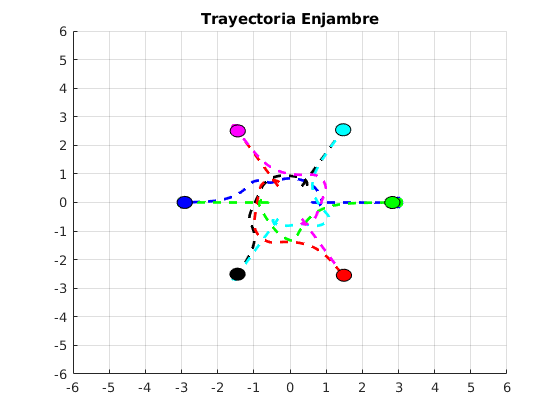

graf=1;
 

close
figure()
hold on

plot(Way1(:,1),Way1(:,2),'bd','LineWidth',2);
plot(Way2(:,1),Way2(:,2),'k+','LineWidth',2);
plot(Way3(:,1),Way3(:,2),'r*','LineWidth',2);
plot(Way4(:,1),Way4(:,2),'gs','LineWidth',2);
plot(Way5(:,1),Way5(:,2),'c*','LineWidth',2);
plot(Way6(:,1),Way6(:,2),'ms','LineWidth',2);

xticks(-6:6)
yticks(-6:6)
r=0.21;

grid on
xlim([-6,6])
ylim([-6,6])
title("Trayectoria Enjambre")
%Inicialización robots
pa1=rectangle('Position',[X1(1)-r Y1(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'b');
plot(X1(1),Y1(1),'b--','LineWidth',2)
pa2=rectangle('Position',[X2(1)-r Y2(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'k');
plot(X2(1),Y2(1),'k--','LineWidth',2)
pa3=rectangle('Position',[X3(1)-r Y3(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'r');
plot(X3(1),Y3(1),'r--','LineWidth',2)
pa4=rectangle('Position',[X4(1)-r Y4(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'g');
plot(X4(1),Y4(1),'g--','LineWidth',2)
pa5=rectangle('Position',[X5(1)-r Y5(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'c');
plot(X5(1),Y5(1),'c--','LineWidth',2)
pa6=rectangle('Position',[X6(1)-r Y6(1)-r 2*r 2*r],'Curvature',[1 1],"FaceColor",'m');
plot(X6(1),Y6(1),'m--','LineWidth',2)

% legend("AutoUpdate","off")
% legend("Way1","Way2","Way3","Way4","Way5","Way6"...
%     ,"Trayectoria1","Trayectoria2","Trayectoria3"...
%     ,"Trayectoria4","Trayectoria5","Trayectoria6","Location","bestoutside")
for i=1:min([length(X1), length(X2),length(X3),length(X4),length(X5),length(X6)])/cte
%     plot(X(i),Y(i),'b>')
%Robot1
    pos1 = [X1(i)-r Y1(i)-r 2*r 2*r]; 
    delete(pa1);
    plot(X1(1:i),Y1(1:i),'b--','LineWidth',2)

%Robot2    
    pos2 = [X2(i)-r Y2(i)-r 2*r 2*r]; 
    delete(pa2);
    if graf==1
        plot(X2(1:i),Y2(1:i),'k--','LineWidth',2)  
    end

%Robot3   
    pos3 = [X3(i)-r Y3(i)-r 2*r 2*r]; 
    delete(pa3);
    plot(X3(1:i),Y3(1:i),'r--','LineWidth',2)
      
%Robot4   
    pos4 = [X4(i)-r Y4(i)-r 2*r 2*r]; 
    delete(pa4);
    if graf==1
        plot(X4(1:i),Y4(1:i),'g--','LineWidth',2)  
    end
     
%Robot5   
    pos5 = [X5(i)-r Y5(i)-r 2*r 2*r]; 
    delete(pa5);
    
    plot(X5(1:i),Y5(1:i),'c--','LineWidth',2)
    
%Robot6   
    pos6 = [X6(i)-r Y6(i)-r 2*r 2*r]; 
    delete(pa6);
    if graf==1
        plot(X6(1:i),Y6(1:i),'m--','LineWidth',2)
    end
        

    
    pa1=rectangle('Position',pos1,'Curvature',[1 1],"FaceColor",'b');    
    pa2=rectangle('Position',pos2,'Curvature',[1 1],"FaceColor",'k');   
    pa3=rectangle('Position',pos3,'Curvature',[1 1],"FaceColor",'r');   
    pa4=rectangle('Position',pos4,'Curvature',[1 1],"FaceColor",'g');
    pa5=rectangle('Position',pos5,'Curvature',[1 1],"FaceColor",'c'); 
    pa6=rectangle('Position',pos6,'Curvature',[1 1],"FaceColor",'m'); 
    
%     legend("Waypoints","Trayectoria Real")
    pause(0.1)
end 
hold off

### Velocidades:

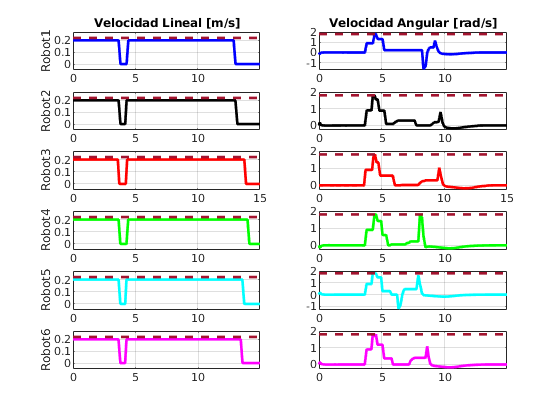

 
figure()
hold on
maxv=0.22;
maxw=1.82;
l1=ones(1,length(t1));
l2=ones(1,length(t2));
l3=ones(1,length(t3));
l4=ones(1,length(t4));
l5=ones(1,length(t5));
l6=ones(1,length(t6));
%R1
subplot(6,2,1)
plot(t1,U1,'b','LineWidth',2);
hold on
plot(t1,maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t1,-maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Lineal [m/s]")
ylabel("Robot1")
ylim([min(U1)-0.05,maxv+0.05])
xlim([0 t1(end)])
grid on
subplot(6,2,2)
plot(t1,W1,'b','LineWidth',2);
hold on
plot(t1,maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t1,-maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Angular [rad/s]")
ylim([min(W1)-0.1,maxw+0.2])
xlim([0 t1(end)])
grid on
%R2
subplot(6,2,3)
plot(t2,U2,'k','LineWidth',2);
hold on
plot(t2,maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t2,-maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U2)-0.05,maxv+0.05])
xlim([0 t2(end)])
ylabel("Robot2")
grid on
subplot(6,2,4)
plot(t2,W2,'k','LineWidth',2);
hold on
plot(t2,maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t2,-maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W2)-0.1,maxw+0.2])
xlim([0 t2(end)])
grid on
%R3
subplot(6,2,5)
plot(t3,U3,'r','LineWidth',2);
hold on
plot(t3,maxv*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t3,-maxv*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U3)-0.05,maxv+0.05])
xlim([0 t3(end)])
ylabel("Robot3")
grid on
subplot(6,2,6)
plot(t3,W3,'r','LineWidth',2);
hold on
plot(t3,maxw*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t3,-maxw*l3,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W3)-0.1,maxw+0.2])
xlim([0 t3(end)])
grid on
%R4
subplot(6,2,7)
plot(t4,U4,'g','LineWidth',2);
hold on
plot(t4,maxv*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t4,-maxv*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U4)-0.05,maxv+0.05])
xlim([0 t4(end)])
ylabel("Robot4")
grid on
subplot(6,2,8)
plot(t4,W4,'g','LineWidth',2);
hold on
plot(t4,maxw*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t4,-maxw*l4,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W4)-0.1,maxw+0.2])
xlim([0 t4(end)])
grid on
%R5
subplot(6,2,9)
plot(t5,U5,'c','LineWidth',2);
hold on
plot(t5,maxv*l5,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t5,-maxv*l5,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U5)-0.05,maxv+0.05])
xlim([0 t5(end)])
ylabel("Robot5")
grid on
subplot(6,2,10)
plot(t5,W5,'c','LineWidth',2);
hold on
plot(t5,maxw*l5,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t5,-maxw*l5,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W5)-0.1,maxw+0.2])
xlim([0 t5(end)])
grid on
%R5
subplot(6,2,11)
plot(t6,U6,'m','LineWidth',2);
hold on
plot(t6,maxv*l6,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t6,-maxv*l6,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(U6)-0.05,maxv+0.05])
xlim([0 t6(end)])
ylabel("Robot6")
grid on
subplot(6,2,12)
plot(t6,W6,'m','LineWidth',2);
hold on
plot(t6,maxw*l6,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
plot(t6,-maxw*l6,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W6)-0.1,maxw+0.2])
xlim([0 t6(end)])
grid on

### LIDAR

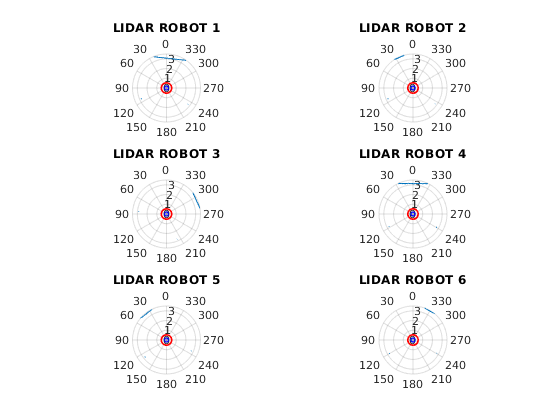

 
% rob=0.5*ones(1,it_max);
RR=VFH.RobotRadius*ones(1,360);
SD=VFH.SafetyDistance+RR;
theta=1:360;
figure
%Robot1
for i=1:min([it_max1,it_max2,it_max3,it_max4,it_max5,it_max6])
  %Robot 1  
  subplot(3,2,1)
  polarplot(Lidar1.angles(i,:),Lidar1.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 1")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
  %Robot 2  
  subplot(3,2,2)
  polarplot(Lidar2.angles(i,:),Lidar2.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 2")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  
  hold off
 %Robot 3  
  subplot(3,2,3)
  polarplot(Lidar3.angles(i,:),Lidar3.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 3")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
 %Robot 4  
  subplot(3,2,4)
  polarplot(Lidar4.angles(i,:),Lidar4.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 4")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
 %Robot 5  
  subplot(3,2,5)
  polarplot(Lidar5.angles(i,:),Lidar5.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 5")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
 %Robot 6  
  subplot(3,2,6)
  polarplot(Lidar6.angles(i,:),Lidar6.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 6")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off 
  pause(0.1) 
  
end

### VFH (Vector Field Histogram):

step=5;

`VFH1:`

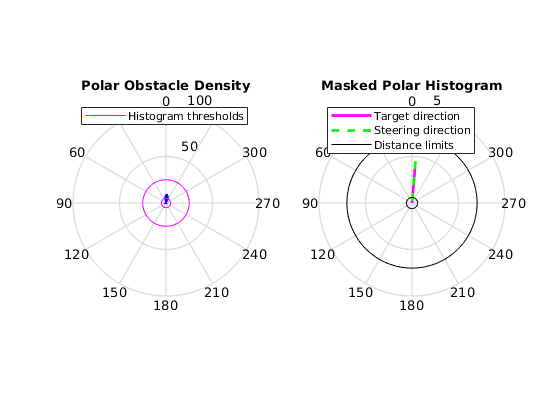

 
for i=1:step:it_max1
%     figure
    scan=lidarScan(Lidar1.ranges(i,:),Lidar1.angles(i,:));
    targetDir =TD1(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH2:`

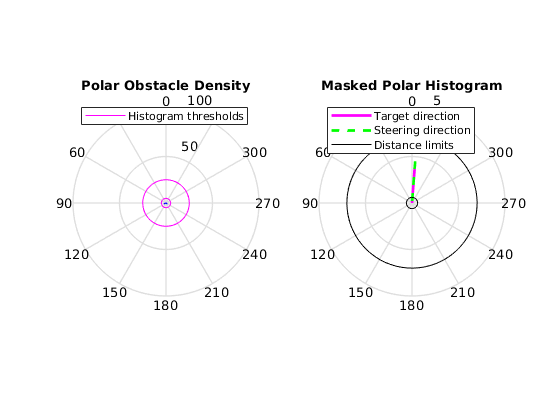

 
for i=1:step:it_max2
%     figure
    scan=lidarScan(Lidar2.ranges(i,:),Lidar2.angles(i,:));
    targetDir =TD2(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH3:`

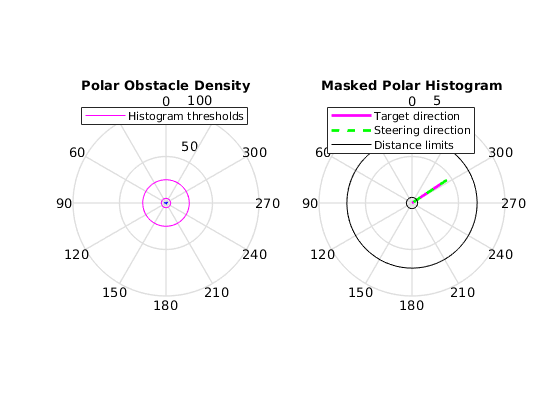

 
for i=1:step:it_max3
%     figure
    scan=lidarScan(Lidar3.ranges(i,:),Lidar3.angles(i,:));
    targetDir =TD3(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH4:`

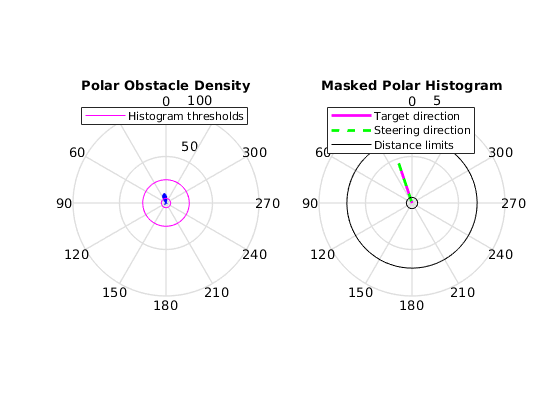

 
for i=1:step:it_max4
    scan=lidarScan(Lidar4.ranges(i,:),Lidar4.angles(i,:));
    targetDir =TD4(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH5:`

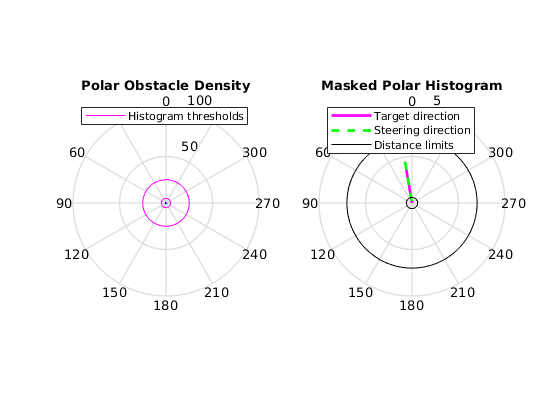

 
for i=1:step:it_max5
    scan=lidarScan(Lidar5.ranges(i,:),Lidar5.angles(i,:));
    targetDir =TD5(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH6:`

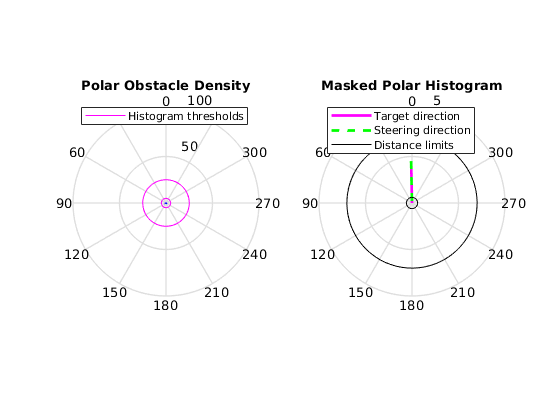

 
for i=1:step:it_max6
    scan=lidarScan(Lidar6.ranges(i,:),Lidar6.angles(i,:));
    targetDir =TD6(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end